# Uso de la función wsa_spectral_parameters

Esta función calcula los parámetros espectrales del oleaje a partir de un espectro de energía. Los parámetros se calculan tanto para el espectro completo, como para las bandas de frecuencia definidas por defecto. También permite el cálculo de bandas personalizadas.

 Bandas por defecto:

- ig     : [1/300, 1/30] Hz

- swell1 : [1/30, 1/12.5] Hz

- swell2 : [1/12.5, 1/8] Hz

- swell  : [1/30, 1/8] Hz

- wind   : [1/8, 1/2] Hz

## Inicialización

clc; clear; close all;

## Datos de entrada

Para mostrar el uso de la función, en la carpeta *\toolbox\example_data* se colocó un struct con datos reales de una campaña de medición de AWAC.

data = load('burst_data.mat');

Para el ejemplo se estimó el espectro basado en una señal de superficie libre medida mediante AST. Para mas información de los datos de entrada y el cálculo de espectros a partir de AST y presión, ver *using_wsa_spectrum.mlx*.

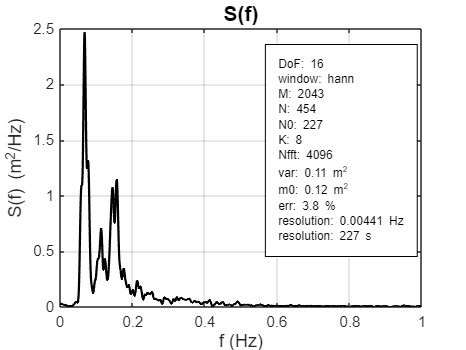

AST = data.burst_data.processed.ast(:, 1);
fs = data.burst_data.general.fs;

[out_Spec, info_Spec] = wsa_spectrum(AST, fs);
f = out_Spec.f;
S = out_Spec.S;

plot_spec(f, S, info_Spec)

## Bandas por defecto

### Utilizando vectores de frecuencia f y densidad espectral S

En el struct de resultados se guardan los parámetros correspondientes a banda total del espectro frecuencial.

out_Spec_Params = wsa_spectral_parameters(f, S)

out_Spec_Params = struct with fields:
                       m0: 0.1156
                       m1: 0.0182
                       m2: 0.0049
                       m4: 0.0014
                  eta_rms: 0.3400
                     Hrms: 0.9616
                      Hm0: 1.3613
                     Tm01: 6.3378
                     Tm02: 4.8436
                       Tp: 14.8406
                       fp: 0.0674
                        v: 0.8439
                       Qp: 1.3949
              band_limits: [0 0.9995]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0 0.9995]
           source_spectra: [1×1 struct]


Los parámetros correspondientes a las bandas por defecto se pueden encontrar en el substruct *bands*

ig = out_Spec_Params.bands.ig

ig = struct with fields:
              m0: 4.1654e-04
              m1: 6.2679e-06
              m2: 1.2569e-07
              m4: 7.7791e-11
         eta_rms: 0.0204
            Hrms: 0.0577
             Hm0: 0.0817
            Tm01: 66.4564
            Tm02: 57.5677
              Tp: 300
              fp: 0.0033
               v: 0.5768
              Qp: 0.9387
     band_limits: [0.0033 0.0333]
    used_spectra: [1×1 struct]


swell1 = out_Spec_Params.bands.swell1

swell1 = struct with fields:
              m0: 0.0393
              m1: 0.0026
              m2: 1.7781e-04
              m4: 8.4169e-07
         eta_rms: 0.1981
            Hrms: 0.5604
             Hm0: 0.7933
            Tm01: 14.9484
            Tm02: 14.8586
              Tp: 14.8406
              fp: 0.0674
               v: 0.1101
              Qp: 5.4109
     band_limits: [0.0333 0.0800]
    used_spectra: [1×1 struct]


swell2 = out_Spec_Params.bands.swell2

swell2 = struct with fields:
              m0: 0.0175
              m1: 0.0018
              m2: 1.9436e-04
              m4: 2.2824e-06
         eta_rms: 0.1324
            Hrms: 0.3745
             Hm0: 0.5302
            Tm01: 9.5754
            Tm02: 9.4985
              Tp: 12.5000
              fp: 0.0800
               v: 0.1275
              Qp: 5.6370
     band_limits: [0.0800 0.1250]
    used_spectra: [1×1 struct]


swell = out_Spec_Params.bands.swell

swell = struct with fields:
              m0: 0.0568
              m1: 0.0045
              m2: 3.7216e-04
              m4: 3.1241e-06
         eta_rms: 0.2383
            Hrms: 0.6740
             Hm0: 0.9542
            Tm01: 12.7409
            Tm02: 12.3530
              Tp: 14.8406
              fp: 0.0674
               v: 0.2526
              Qp: 3.1228
     band_limits: [0.0333 0.1250]
    used_spectra: [1×1 struct]


wind = out_Spec_Params.bands.wind

wind = struct with fields:
              m0: 0.0546
              m1: 0.0112
              m2: 0.0027
              m4: 2.5745e-04
         eta_rms: 0.2337
            Hrms: 0.6610
             Hm0: 0.9357
            Tm01: 4.8661
            Tm02: 4.4896
              Tp: 6.4000
              fp: 0.1562
               v: 0.4181
              Qp: 2.8574
     band_limits: [0.1250 0.5000]
    used_spectra: [1×1 struct]


### Utilizando el struct de salida de *wsa_spectrum*

También es posible pasar el struct de salida de wsa_spectrum a la función. En general, se puede emplear cualquier struct que contenga los campos f y S, mientras sean consistentes en tamaño.

out_Spec_Params = wsa_spectral_parameters(out_Spec) %#ok<NASGU>

out_Spec_Params = struct with fields:
                       m0: 0.1156
                       m1: 0.0182
                       m2: 0.0049
                       m4: 0.0014
                  eta_rms: 0.3400
                     Hrms: 0.9616
                      Hm0: 1.3613
                     Tm01: 6.3378
                     Tm02: 4.8436
                       Tp: 14.8406
                       fp: 0.0674
                        v: 0.8439
                       Qp: 1.3949
              band_limits: [0 0.9995]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0 0.9995]
           source_spectra: [1×1 struct]


## Bandas modificadas

### Modificando la banda total

Es posible modificar la banda frecuencial total, esto cambia el resultado del struct principal, pero no modifica el resto de bandas por defecto predefinidas.

out_Spec_Params = wsa_spectral_parameters(f, S, 'TotalBand', [1/25 1/5]) %#ok<NASGU>

out_Spec_Params = struct with fields:
                       m0: 0.0925
                       m1: 0.0100
                       m2: 0.0012
                       m4: 2.5086e-05
                  eta_rms: 0.3042
                     Hrms: 0.8603
                      Hm0: 1.2178
                     Tm01: 9.2540
                     Tm02: 8.6406
                       Tp: 14.8406
                       fp: 0.0674
                        v: 0.3835
                       Qp: 2.0658
              band_limits: [0.0400 0.2000]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0400 0.2000]
           source_spectra: [1×1 struct]


### Redefiniendo bandas por defecto

Para redefinior las bandas por defecto, se debe crear un struct cuyos campos sean del tipo 'nombre', [fmin, fmax]. De esta forma puede verificarse en el substruct *band_definitions* los nuevos límites. Los parámetros en *bands* ahora corresponden a estos límites.

redefined_bands = struct('ig', [1/350, 1/25], ...
                         'wind', [1/8, 1/5]);
out_Spec_Params = wsa_spectral_parameters(f, S, 'Bands', redefined_bands);
out_Spec_Params.band_definitions

ans = struct with fields:
        ig: [0.0029 0.0400]
    swell1: [0.0333 0.0800]
    swell2: [0.0800 0.1250]
     swell: [0.0333 0.1250]
      wind: [0.1250 0.2000]


### Agregando nuevas bandas

Para agregar bandas personalizadas, estas se definen mediante un struct cuyos campos sean del tipo 'nombre', [fmin fmax]. Estas bandas se agregan al substruct *bands*.

new_bands = struct('Banda1', [1/350, 1/25], ...
                   'wind2', [1/2, 1]);
out_Spec_Params = wsa_spectral_parameters(f, S, 'CustomBands', new_bands);
out_Spec_Params.band_definitions

ans = struct with fields:
        ig: [0.0033 0.0333]
    swell1: [0.0333 0.0800]
    swell2: [0.0800 0.1250]
     swell: [0.0333 0.1250]
      wind: [0.1250 0.5000]
    Banda1: [0.0029 0.0400]
     wind2: [0.5000 1]



Banda1 = out_Spec_Params.bands.Banda1

Banda1 = struct with fields:
              m0: 5.5201e-04
              m1: 1.0871e-05
              m2: 2.9634e-07
              m4: 3.1775e-10
         eta_rms: 0.0235
            Hrms: 0.0665
             Hm0: 0.0941
            Tm01: 50.7782
            Tm02: 43.1597
              Tp: 25
              fp: 0.0400
               v: 0.6198
              Qp: 1.1575
     band_limits: [0.0029 0.0400]
    used_spectra: [1×1 struct]


wind2 = out_Spec_Params.bands.wind2

wind2 = struct with fields:
              m0: 0.0037
              m1: 0.0026
              m2: 0.0018
              m4: 0.0011
         eta_rms: 0.0607
            Hrms: 0.1718
             Hm0: 0.2432
            Tm01: 1.4452
            Tm02: 1.4139
              Tp: 1.8092
              fp: 0.5527
               v: 0.2115
              Qp: 3.3992
     band_limits: [0.5000 1]
    used_spectra: [1×1 struct]


### No incluir bandas por defecto

Es posible eliminar las bandas por defecto del cálculo.

out_Spec_Params = wsa_spectral_parameters(f, S, 'IncludeDefaultBands', false)

out_Spec_Params = struct with fields:
                       m0: 0.1156
                       m1: 0.0182
                       m2: 0.0049
                       m4: 0.0014
                  eta_rms: 0.3400
                     Hrms: 0.9616
                      Hm0: 1.3613
                     Tm01: 6.3378
                     Tm02: 4.8436
                       Tp: 14.8406
                       fp: 0.0674
                        v: 0.8439
                       Qp: 1.3949
              band_limits: [0 0.9995]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0 0.9995]
           source_spectra: [1×1 struct]


out_Spec_Params.band_definitions

ans = struct with no fields.
